% Jocelyn Espinoza - Prelim Design Code

t = 3; % 3 hours

GW_initial = 13000; %lbfs for the original XV-15 design from book

SFC = 0.6; %lb/lbf hr -> assume it is the same as T53-L-138: 0.60

engine_cont_power = 1250; %shp from book!

Pa = 2*engine_cont_power; %shp

Pa_in_kw = (Pa*745.7)/1000;

W_f = SFC*Pa *t; % Weight of fuel in lbf

mass_person = 100; % IN KG given by the RFP

person_force_Newton = mass_person * 9.81; %In newtons

W_person_lbf = person_force_Newton * (1/4.448222); % Converting to lbf

w_2_people = W_person_lbf*2; % Weight of 2 ppl

% Calculating new stuff for our HEPS!

% P required for our vehicle is the highest at climb, 2500 shp total

W_motor_kg = 22 % kg -> 215.82N

W_motor_kg = 22


W_motors = 215.82*2; %lbf

W_batteries = 0; %lbf

load_fraction_target = 0.28;  % Desired useful load fraction
tolerance = 5;               % lbf tolerance
increment = 5;               % lbf decrement step
max_iterations = 1000;

iteration = 0;

W_payload_last = 1148;

 W_u_new = W_f + w_2_people + W_payload_last;
 GW_new  = W_u_new / load_fraction_target;

 GW_target = 13000;

 while iteration < max_iterations
    % Compute new useful load and gross weight
    W_u_new = (0.95*W_f) + w_2_people + W_payload_last;
    GW_new  = W_u_new / load_fraction_target;

    % Stop when GW_new is close to target
    if abs(GW_new - GW_target) < tolerance || W_payload_last <= 0
        break
    end

    % If GW_new is higher than target, reduce payload
    if GW_new > GW_target
        W_payload_last = max(W_payload_last - increment, 0);
    else
        % If it's too low (rare case), increase payload slightly
        W_payload_last = W_payload_last + increment;
    end

    iteration = iteration + 1;
end

% --- Display results ---
fprintf('Converged after %d iterations:\n', iteration);

Converged after 230 iterations:


fprintf('Payload = %.2f lb\n', W_payload_last);

Payload = 0.00 lb


fprintf('Gross Weight = %.2f lb\n', GW_new);

Gross Weight = 16843.13 lb


fprintf('Useful Load Fraction = %.3f\n', W_u_new / GW_new);

Useful Load Fraction = 0.280



% Pie chart!!!

W_engines = 549*2; %lbf from smithsonian website

W_generator = 290; %lbf

W_payload_last = 1431

W_payload_last = 1431


W_structure = 13002.69 - w_2_people - W_payload_last - (W_f) - W_batteries - W_motors - W_engines - W_generator;

W_fuel = W_f

W_fuel = 4500

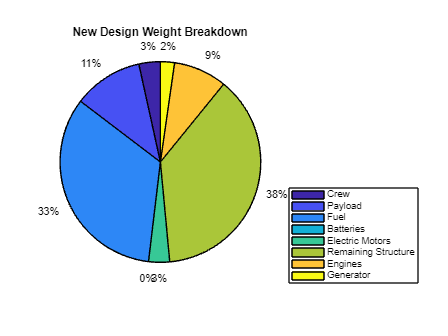


values = [w_2_people, W_payload_last, (0.95*W_f), W_batteries, W_motors, W_structure, W_engines, W_generator];
labels = ["Crew", "Payload","Fuel", "Batteries", "Electric Motors","Remaining Structure", "Engines","Generator"];
figure;
h = pie(values);

title('New Design Weight Breakdown');
legend(labels, 'Location','southeastoutside');


W_struct_total = W_generator + W_motors + W_engines + W_structure + W_batteries;

%Payload Range Diagram!

% Weights -> Phase 1 Design
V_cruise = 260; %knots
V_cruise_fts = 438.830563; %ft/s
V_cruise_ft_hr = V_cruise_fts*(60/1)*(60/1);
LD = 10;

MTOW = 13002.69;
W_empty = 7.8016*10^3;
W_fuel = 4275;

MaxPayload_phaseI = 485;

payload_phaseI = linspace(MaxPayload_phaseI,0,50); % Going from max payload to 0 to see what happens to the range

fuel_phaseI = zeros(size(payload_phaseI));

for i = 1:length(payload_phaseI)
    fuel_allowed_by_MTOW = MTOW - W_empty - payload_phaseI(i);

    if fuel_allowed_by_MTOW > W_fuel
        fuel_phaseI(i) = W_fuel;
    else
        fuel_phaseI(i) = fuel_allowed_by_MTOW;
    end
end

W_initial = W_empty + payload_phaseI + fuel_phaseI + w_2_people;
W_final = W_initial - fuel_phaseI;

S = (V_cruise_ft_hr./(SFC)) .* LD .* log(W_initial./W_final); % ft

S_nm = S* (1/6076) %ft to nautical miles conversion

S_nm = 1.0e+03 *

    1.7275    1.7292    1.7308    1.7324    1.7340    1.7357    1.7373    1.7389    1.7406    1.7422    1.7439    1.7455    1.7472    1.7488    1.7505    1.7521    1.7538    1.7555    1.7571    1.7588    1.7605    1.7622    1.7638    1.7655    1.7672    1.7689    1.7706    1.7723    1.7740    1.7757    1.7774    1.7791    1.7809    1.7826    1.7843    1.7860    1.7878    1.7895    1.7912    1.7930    1.7947    1.7965    1.7982    1.8000    1.8017    1.8035    1.8053    1.8070    1.8088    1.8106


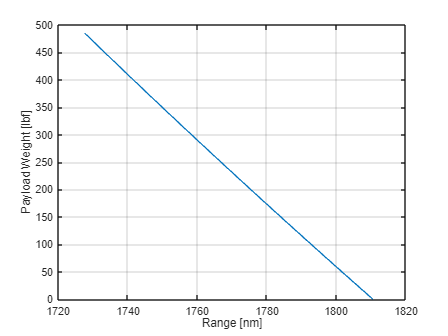


% Plotting for the original XV-15


figure;
plot(S_nm, payload_phaseI);
ylabel('Payload Weight [lbf]')
xlabel('Range [nm]')
grid on;